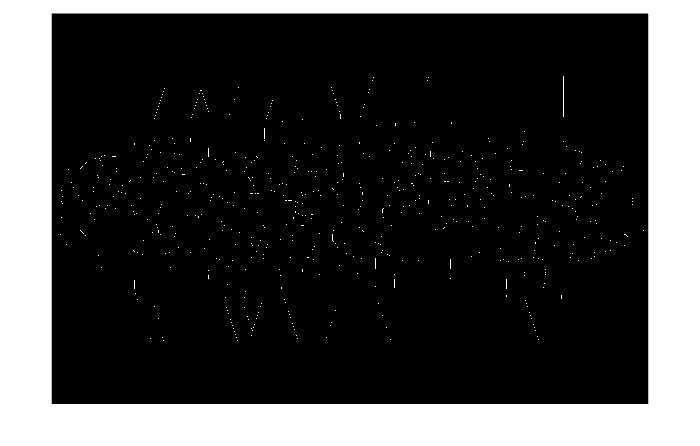

ans = 'reorganizing network'

Hello
Hello


ans = 'Calculate Connectivity'

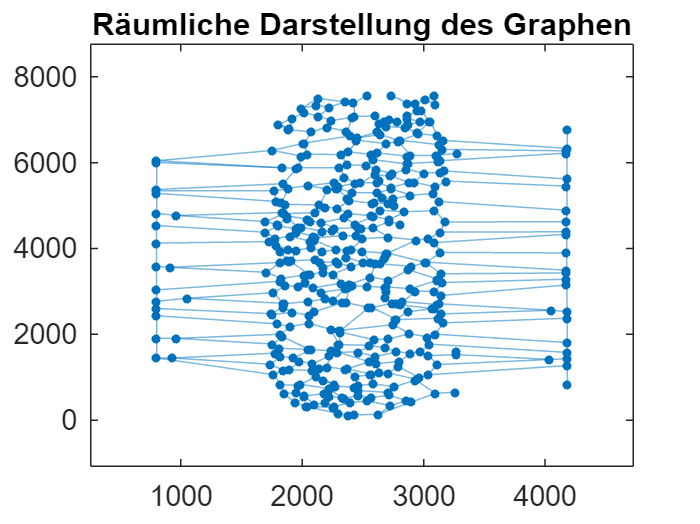

ans = 'Reorient Network'

ans = 0

ans = 0


%%%%%% First part creates a connectivity matrix based on a skeleton of a
%%%%%% brightfield image -> regular part of the skeleton pipeline



data_files = {
    'bw6';


};

suff = '.tif'; 


for k = 1:1
      ttb = 0;
      bw = imread(strcat(data_files{k}, suff));

      % bw = imread('/Usenuchftdfanmen en eers/leonie/Desktop/Mask/d2_frm231128_flw_0-5_btt_day9_day12-1_mask copy/d2_frm231128_flw_0-5_btt_day9_day12-1_mask-0001.tif');
      % bw   = imcomplement(bw);  % umdrehen
      pores = double(bw / 255);
      offsety = 1470;
      % offsetx = 2628; 
      Ny = size(pores, 1);
      Nx = size(pores, 2);
      pores(:, 1) = 0;
      pores(:, end) = 0;
      pores = [zeros(10,Nx);ones(offsety-1, Nx); pores; ones(offsety-1, Nx);zeros(10,Nx)];
      ny_2 = size(pores, 1);
      px_rm = 0;
      for i = 1:1:px_rm
          pores(offsetx + i, 2628:end-2547) = 1;
          pores(ny_2 - offsetx - i + 1, 2547:end-2628) = 1;
      end  
      pores(:,1:50)=0;
      pores(:,end-50:end)=0;
      
     
     BW_composition = imbinarize(pores);
     BW_composition = medfilt2(BW_composition);
     BWao = bwareaopen(imcomplement(BW_composition),15);
     BW_composition=imclose(imcomplement(BWao), strel('disk', 2));
     BW_skeleton = bwskel(BW_composition, 'MinBranchLength', 20);
     BW_skeleton = bwmorph(BW_skeleton,'skel',inf);
     BW = pores;
     pores = BW_composition;
    y_value_upper = offsety;
    Ny = 2530;
    y_value_lower = y_value_upper+Ny;
        
    x_value_upper = 1200;
    x_value_lower = 6400;


    x_value_inlet =1000 ;
    [Dmask,out_15] = calculateDmask(BW_skeleton, y_value_upper, Ny, x_value_inlet);
    out_15 = imbinarize(out_15);
    [Dmask,out_15] = calculateDmask(out_15, y_value_upper, Ny, x_value_inlet);
    out_15 = imbinarize(out_15);
    [Dmask,out_15] = calculateDmask(out_15, y_value_upper, Ny, x_value_inlet);
    out_15 = bwmorph(out_15,'skel',inf);
    dummy = out_15;
    [Dmask,out_15] = calculateDmask(out_15, x_value_upper, Ny, x_value_inlet);
    out_15 = bwmorph(out_15,'skel',inf);
    dummy = out_15;
    [network_edges, network_vertices, branch, imbranch] = FindBranchesPores('./', out_15, pores);
       
    save('branch.mat', 'branch');


        
    imshow(BW_skeleton);

    'reorganizing network'
    % deloop network
    for i = 1:1:size(network_edges,1)
        % detect loops
        seso = find(ismember(network_edges(i+1:end,:),network_edges(i,:),'rows')>0);
        seso = seso + i;
        sero = find(ismember(network_edges(1:end,:),fliplr(network_edges(i,:)),'rows')>0);
        % if loop detected add vertex at center of branch and create new edge
        if ~isempty(seso) || ~isempty(sero)
            disp("Hello")
            nvind = ceil(size(branch{i},1)/2);
            newvertex = branch{i}(nvind,1:2);
            % new branch
            branch{size(network_edges,1)+1} = branch{i}(nvind:end,:);
            branch{i}(nvind+1:end,:) = [];
            % new edge
            network_edges = [network_edges; size(network_vertices,1)+1,network_edges(i,2)];
            network_edges(i,2) = size(network_vertices,1)+1;
            % new vertex
            network_vertices = [network_vertices;newvertex];
            assert(size(unique(network_edges),1) == size(network_vertices,1))
        end
    end
    assert(size(unique(network_edges),1) == size(network_vertices,1))


%Find in and Outflow vertices
    vertices = network_vertices;
    edges = network_edges;
    % Definiere den Bereich für y, den du verwenden möchtest
    min_y = 0; % untere Grenze des y-Bereichs
    max_y = offsety; % obere Grenze des y-Bereichs
    % Finde die Indizes der Vertices, deren y-Werte innerhalb des Bereichs liegen
    y_in_range = find(vertices(:,1) >= min_y & vertices(:,1) <= max_y);
    % Jetzt suche das Minimum und Maximum von x in dem eingeschränkten y-Bereich
    [minx, minx_idx] = min(vertices(y_in_range,2));
    % Hole die tatsächlichen Indizes in der ursprünglichen vertices-Liste
    sted =find(vertices(:,2)==minx);% Index des Minimums in x

    min_y = size(pores,1) - offsety; % untere Grenze des y-Bereichs
    max_y = size(pores,1); % obere Grenze des y-Bereichs
    % Finde die Indizes der Vertices, deren y-Werte innerhalb des Bereichs liegen
    y_in_range_ = find(vertices(:,1) >= min_y & vertices(:,1) <= max_y);
    [maxx, maxx_idx] = max(vertices(y_in_range_,2));
    ened =find(vertices(:,2)==maxx);
    novert = size(vertices, 1);
    if(ttb)
        placeholder = sted;
        sted=ened;
        ened = placeholder;
        disp('yes')
    end    
    %If there are two vertices witht he same y coordinate
    if length(sted)>1
        if vertices(sted(1),1)<vertices(sted(2),1)
            sted=sted(1);
        else
            sted=sted(2);
        end    
    end   

    if length(ened)>1
        if vertices(ened(1),1)>vertices(ened(2),1);
            ened = ened(1);
        else
            ened=ened(2);
        end
    end    

    stbranch = branch{sted};
    branch{sted} = branch{1};
    branch{1} = stbranch;
    edges(edges==1) = novert +1;
    edges(edges==sted) = 1;
    edges(edges==novert+1) = sted;
    stvert = vertices(sted,:);
    vertices(sted,1:2) = vertices(1,1:2);
    vertices(1,1:2) = stvert;
    
    enbranch = branch{ened};
    branch{ened} = branch{novert};
    branch{novert} = enbranch;
    edges(edges==novert) = novert +1;
    edges(edges==ened) = novert;
    edges(edges==novert+1) = ened;
    envert = vertices(ened,:);
    vertices(ened,1:2) = vertices(novert,1:2);
    vertices(novert,1:2) = envert;
    assert(size(unique(edges),1) == size(vertices,1))
    
    
    
    'Calculate Connectivity'
    network_C_1 = zeros(size(unique(edges),1));
    for i = 1:1:size(edges,1)
        network_C_1(edges(i,1),edges(i,2)) = network_C_1(edges(i,1),edges(i,2)) + 1;
    end
    network_C_1 = network_C_1 + network_C_1';
    
    % figure; 
    % plot_network(network_C_1,vertices,0,'off');
    
    maxlen = 0;
    veced = zeros(size(edges,1),2);
    lened = zeros(size(edges,1),1);
    for i = 1:1:size(edges,1)
        inorg = edges(i,1);
        indest = edges(i,2);
        org = vertices(inorg,:);
        dest = vertices(indest,:);
    
        % Check if the condition is met before swapping vertices
        if dest(1) < org(1)
            edges(i,1) = indest;
            edges(i,2) = inorg;
            branch{i} = flipud(branch{i});
        end
        
        lened(i) = sqrt(sum((org - dest).^2));
        veced(i,:) = (org - dest)/lened(i);
        
        if size(branch{i},1) > maxlen
            maxlen = size(branch{i},1);
        end
    end
    
    G = graph(network_C_1);
    figure; plot(G, 'XData', vertices(:,1), 'YData', vertices(:,2));
    title('Räumliche Darstellung des Graphen');

    % also reorient network_... version, as this is the one to determine radii
    'Reorient Network'
    for i = 1:1:size(network_edges,1)
        inorg = network_edges(i,1);
        indest = network_edges(i,2);
        org = network_vertices(inorg,:);
        dest = network_vertices(indest,:);
        if(ttb)
            if dest(1) > org(1)
                network_edges(i,1) = indest;
                network_edges(i,2) = inorg;
            end
        else    
            if dest(1) < org(1)
                network_edges(i,1) = indest;
                network_edges(i,2) = inorg;
            end
        end   
    end    
    
    out_15 = BW_skeleton;
    LC = pores;
    nanMask = isnan(LC);
    
    % Create a temporary matrix where NaN values are replaced with 0
    LC_no_nan = LC;
    LC_no_nan(nanMask) = 0;
    
    % Invert (flip) the values in the temporary matrix
    flippedLC_no_nan = ~LC_no_nan;
    
     % Restore the NaN values in the flipped matrix using the mask
     flippedLC = flippedLC_no_nan;
     % flippedLC(nanMask) = NaN;
    
    LCext = out_15;
    % LCext = skel;
    [DD,~] = bwdist(flippedLC);
    
    % distance to closest neighbor, i.e. radius
    D = zeros(size(DD));
    %D(skel)= DD(skel);
    %if skel with bwmorph is skipped before
    skel =LCext;
    skel(skel>1)=1;
    skel_logical = logical(skel);
    D(skel_logical)= DD(skel_logical);
    % D(skelred) = DD(skelred); Auskommentiert 31.8.23
    imdiam = 2*D; 
    
    % convert into cell structure
    diameter = cell(1,length(edges));
    gradbr = cell(1,length(edges));
    for i=1:1:length(edges)
        % muss man was reinschreiben was passieren soll wenn branch empty
        if isempty(branch{i});
            continue;
        end
        diameter{i} = imdiam(sub2ind(size(LC),branch{i}(:,1),branch{i}(:,2)));

        
        %parametric vector to walk along the branch to determine local gradient
        mybranch = branch{i};
        x=mybranch(:,1);
        y=mybranch(:,2);
        t=cumsum([0; sqrt( diff(x).^2 + diff(y).^2 )] );
        t1 = zeros(1,5*length(t)-5);
        for j=1:length(t)-1
            t1(5*(j-1)+1:5*j)=linspace(t(j),t(1+j),5);
        end
        %fit a spline
        x1=spline(t, x, t1);
        y1=spline(t, y, t1);
        %store the gradient along branch
        vec = [gradient(x1)',gradient(y1)'];
        vecp = [vec(1:5:end,:);vec(end,:)];
        gradbr{i} = vecp./repmat(sqrt(sum(vecp.*vecp,2)),1,2);
    end
    
    nandiam = zeros(size(edges,1),1);
    zerodiam = zeros(size(edges,1),1);
    
    for i = 1:1:size(edges,1)
        nandiam(i) = sum(isnan(diameter{i}));
        zerodiam(i) = sum(diameter{i}==0);
    end
    sum(nandiam)
    sum(zerodiam)
    assert(sum(nandiam)==0)
     % assert(sum(zerodiam)==0)
    
    cutOffTrig = 25;
    % calculate connectivity
    C_net = zeros(size(unique(edges),1));
    for i = 1:1:size(edges,1)
        C_net(edges(i,1),edges(i,2)) = C_net(edges(i,1),edges(i,2)) + 1;
    end
    C_net = C_net + C_net';
     % assert(sum(sum(full(C_net)>1)) == 0);

   dx = 0.828333*10^(-6);
   x = 7.2*10^(-6); % resolution one pixel in meter
   J= 5*10^(-10)/60;% in m^3/s
   height = 80*10^(-6);
   ascal = dx; % diameter scale in mikrometer
    seg = 1; 
    viscosity = 9.4*10^(-4);
    [U,P,Q,R,R_2,U_2,For_digraph,For_graph,energy_dissipation,efficiency,deltaP,volume_sum,counter]= calculate_poiseuilleflow_july(C_net,edges,diameter,dx,J,ascal,viscosity); 
    save(strcat(data_files{k}, '_C_net.mat'), 'C_net');
    save(strcat(data_files{k}, '_edges.mat'), 'edges');
    save(strcat(data_files{k}, '_diameter.mat'), 'diameter');
    save(strcat(data_files{k}, '_BW_skeleton.mat'), 'BW_skeleton');
    save(sprintf('U_time_%d.mat', k), 'U');
    save(sprintf('Q_time_%d.mat', k), 'Q');
    
    
    
    % [U,P,Q,R,R_3,Q_2,U_2,deltaP,RR,KK,K] = calculate_poiseuilleflow(C_net,edges,diameter,dx,J,ascal);
    out_15 = dummy;
    LC = pores;
    nanMask = isnan(LC);
    
    % Create a temporary matrix where NaN values are replaced with 0
    LC_no_nan = LC;
    LC_no_nan(nanMask) = 0;
    
    % Invert (flip) the values in the temporary matrix
    flippedLC_no_nan = ~LC_no_nan;
    
     % Restore the NaN values in the flipped matrix using the mask
     flippedLC = flippedLC_no_nan;
     % flippedLC(nanMask) = NaN;
    
    LCext = out_15;
    % LCext = skel;
    [DD,~] = bwdist(flippedLC);
    
    % distance to closest neighbor, i.e. radius
    D = zeros(size(DD));
    %D(skel)= DD(skel);
    %if skel with bwmorph is skipped before
    skel =LCext;
    skel(skel>1)=1;
    skel_logical = logical(skel);
    D(skel_logical)= DD(skel_logical);
    % D(skelred) = DD(skelred); Auskommentiert 31.8.23
    imdiam = 2*D; 
    results{k} = [energy_dissipation,counter,Q,R];
 

    u2comp = cell(size(U));
    v2comp = cell(size(U));
    for i = 1:1:size(network_edges,1)
        comp = repmat(U{i}',2,1)'.*gradbr{i};
        u2comp{i} = comp(:,1);
        v2comp{i} = comp(:,2);
    end
    
    % evaluate velocities along branch into image and create pixel resolution
    % map of velocity
    imuu = zeros(size(BW));
    imgradx = zeros(size(BW));
    imgrady = zeros(size(BW));
    imq = zeros(size(BW));
    imdiam = zeros(size(BW));
    for i = 1:1:size(branch,2)
        mybranch = branch{i};
        mybranch_ind = sub2ind(size(BW),mybranch(:,1),mybranch(:,2));
        %add branch to image
        imuu(mybranch_ind) = U{i};
        imgradx(mybranch_ind) = gradbr{i}(:,1);
        imgrady(mybranch_ind) = gradbr{i}(:,2);
        imdiam(mybranch_ind) = diameter{i};
        imq(mybranch_ind) = repmat(Q(i),size(U{i}));
    end
    
    
    
    imuuarray = imuu';
    imuuarray = imuuarray(:);
    max_axis = max(max(imuu(imuu>0)));
    min_axis = min(min(imuu(imuu>0)));
    mean_axis = mean(mean(imuu(imuu>0)));
    std_axis = std(imuuarray(imuuarray>0));
end

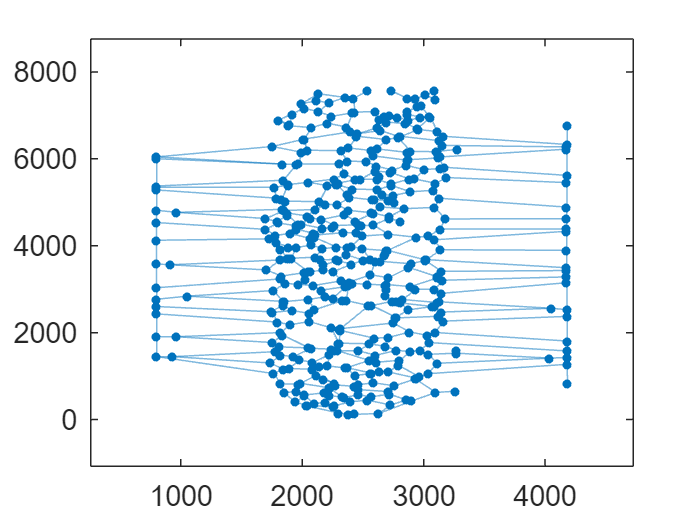

%}





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%





%%%%%% Second part extracts the coorcinates to make it a network with 
%%%%%% specific node coordinates and edge lengths


G = graph(network_C_1);
h = plot(G, 'XData', vertices(:,1), 'YData', vertices(:,2));



X = h.XData(:);  % X coordinates of nodes
Y = h.YData(:);  % Y coordinates of nodes



num_edges = size(edges, 1);
L = zeros(num_edges, 1);

for i = 1:num_edges
    n1 = edges(i, 1);
    n2 = edges(i, 2);
    dx = X(n1) - X(n2);
    dy = Y(n1) - Y(n2);
    L(i) = sqrt(dx^2 + dy^2);  % edge length in pixels
end



nw.C = network_C_1;
nw.edge = edges;
nw.n_seg = size(edges,1);
nw.n_vertex = size(network_C_1,1);

dx = 0.1;  % mm 
for i = 1:nw.n_seg
    nw.n_box(i) = max(1, round(L(i) / dx));  % discretize by length
    nw.diameter{i} = 0.2 * ones(nw.n_box(i), 1);  % uniform diameter in mm
    nw.eta{i} = nw.diameter{i} / 2;              % assign eta (radius), same length as diameter
end


% optional, can add node coords here
nw.X = X;
nw.Y = Y;
nw.L = L;




%save

mkdir('data');
save('data/i_network_variables.mat', 'nw');
save('data/X_coord_network.mat', 'X');
save('data/Y_coord_network.mat', 'Y');
save('data/L_lengths.mat', 'L');

fprintf('Saved network structure, coordinates, and lengths for absorption code.\n');

Saved network structure, coordinates, and lengths for absorption code.




%}











%%%%%%%%%%%%%% saving network bundle for further analysis tools

V = double(vertices);          % N×2  [y, x] in pixels
E = double(edges);             % M×2  1-based indices into V
C = sparse(network_C_1);       % N×N  adjacency

% Edge polyline lengths (already computed as L)
if ~exist('L','var') || isempty(L)
    num_edges = size(E,1);
    L = zeros(num_edges,1);
    for i = 1:num_edges
        n1 = E(i,1); n2 = E(i,2);
        dy = V(n1,1) - V(n2,1);
        dx = V(n1,2) - V(n2,2);
        L(i) = hypot(dy, dx);               % in pixels
    end
end

% Mean diameter per edge (pixels)
M = numel(diameter);
diam_mean_px = zeros(M,1);
for i = 1:M
    if isempty(diameter{i})
        diam_mean_px(i) = NaN;
    else
        di = diameter{i};
        di = di(~isnan(di) & isfinite(di) & di>0);
        diam_mean_px(i) = mean(di, 'omitnan');
    end
end

% Velocity samples are U{i}; compute per-edge mean
U_mean = zeros(M,1);
if exist('U','var') && numel(U)==M
    for i=1:M
        ui = U{i};
        if isempty(ui)
            U_mean(i) = NaN;
        else
            U_mean(i) = mean(ui, 'omitnan');
        end
    end
else
    U_mean(:) = NaN;
end

% Node degree
deg = full(sum(C>0, 2));

% Units/scale metadata
meta = struct();
meta.pixel_size_m_primary   = 0.828333e-6;     % meters per pixel (DX)
meta.pixel_size_m_alt       = 7.2e-6;          % meters per pixel (X) if applicable
meta.height_m               = 80e-6;           % channel height used in flow model
meta.viscosity_Pa_s         = 9.4e-4;
meta.inflow_m3_per_s        = 5e-10/60;
meta.offsety                = exist('offsety','var') * offsety;
meta.x_window               = [exist('x_value_upper','var') * x_value_upper, ...
                               exist('x_value_lower','var') * x_value_lower];
meta.y_window               = [exist('y_value_upper','var') * y_value_upper, ...
                               exist('y_value_lower','var') * y_value_lower];
meta.params                 = struct('MinBranchLength', 20, ...
                                     'medfilt', true, ...
                                     'bwareaopen_thresh', 15);

px_m = meta.pixel_size_m_primary;
L_m  = L * px_m;
diam_mean_m = diam_mean_px * px_m;

% Pack struct
nw = struct();
nw.V           = V;                   % N×2 [y,x] px
nw.E           = E;                   % M×2
nw.C           = C;                   % N×N sparse
nw.branch      = branch;              % {M×1} polyline coords (px)
nw.diameter    = diameter;            % {M×1} samples (px)
nw.diam_mean_px= diam_mean_px;        % M×1
nw.diam_mean_m = diam_mean_m;         % M×1
nw.L_px        = L;                   % M×1
nw.L_m         = L_m;                 % M×1

% Flow results 
if exist('Q','var'),  nw.Q = Q(:); else, nw.Q = []; end
if exist('R','var'),  nw.R = R(:); else, nw.R = []; end
if exist('U','var'),  nw.U_samples = U; else, nw.U_samples = {}; end
nw.U_mean = U_mean;   
if exist('P','var'),  nw.P_node = P(:); else, nw.P_node = []; end


% Node roles
nw.inlet_id    = exist('sted','var')  * sted;
nw.outlet_id   = exist('ened','var')  * ened;

% Images (optional)
nw.images = struct('BW_skeleton', exist('BW_skeleton','var') * BW_skeleton, ...
                   'pores',       exist('pores','var')       * pores, ...
                   'imdiam',      exist('imdiam','var')      * imdiam);

% Misc
nw.deg       = deg;
nw.meta      = meta;
nw.created_on= datestr(now, 30);

src = struct();
if exist('data_files','var') && ~isempty(data_files)
    src.file = data_files;
else
    src.file = {};
end

if exist('suff','var')
    src.suffix = suff;
else
    src.suffix = '';
end
nw.source = src;


%% Save block

% Choose base name 
if exist('data_files','var') && ~isempty(data_files)
    base = char(data_files{1});
else
    base = 'network';
end

outdir = 'data';
if ~exist(outdir, 'dir'), mkdir(outdir); end

% MAT file (v7.3 for big cells)
save(fullfile(outdir, [base '_nw.mat']), 'nw', '-v7.3');

% Lightweight CSVs for quick interop (Python, Julia, etc.)
writematrix(nw.V,        fullfile(outdir, [base '_vertices_px.csv']));
writematrix(nw.E,        fullfile(outdir, [base '_edges.csv']));
writematrix([nw.L_px, nw.L_m],    fullfile(outdir, [base '_edge_lengths_px_m.csv']));
writematrix([nw.diam_mean_px, nw.diam_mean_m], fullfile(outdir, [base '_edge_diam_mean_px_m.csv']));
if ~isempty(nw.Q), writematrix(nw.Q, fullfile(outdir, [base '_edge_Q.csv'])); end
if ~isempty(nw.U_mean), writematrix(nw.U_mean, fullfile(outdir, [base '_edge_Umean.csv'])); end

% JSON sidecar with metadata
try
    meta_json = jsonencode(nw.meta);
    fid = fopen(fullfile(outdir, [base '_meta.json']), 'w'); fwrite(fid, meta_json); fclose(fid);
catch
    warning('Could not write JSON metadata (jsonencode not available?).');
end

fprintf('Saved canonical bundle to %s\n', fullfile(outdir, [base '_nw.mat']));

Saved canonical bundle to data\bw6_nw.mat




%save image
% Save skeleton as image (black/white)
imwrite(uint8(nw.images.BW_skeleton)*255, fullfile(outdir, [base '_skeleton.png']));


%and graph
% Save graph plot as an image
fig = figure('Visible','off'); 
G = graph(nw.C);
plot(G, 'XData', nw.V(:,1), 'YData', nw.V(:,2), 'NodeColor','r','MarkerSize',4,'EdgeColor','b');
axis equal tight;
title(sprintf('Graph: %s', base), 'Interpreter','none');
saveas(fig, fullfile(outdir, [base '_graph.png']));
close(fig);




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%










%% Absorption Calculation

% old call (ignore)
% [U_cell,P,Q,R_res, R2, U2, ~, ~, ~, ~, deltaP, ~, ~] = ...
%    calculate_poiseuilleflow_july(C_net, edges, diameter, dx, J, ascal, viscosity);

% 1) Build velocity vector U_vec [E×1]
%    (we take the mean of the fine‐grained U_cell{i} along each branch)
E = size(edges,1);
U_vec = zeros(E,1);
for i = 1:E
  U_vec(i) = mean(U{i});   % use U{i} (not U_cell{i})
end


% 2) Pressure drops per edge (Pa).  
%    The flow code returned deltaP as an E×1 or 1×E vector already:
pressurediff = deltaP(:)';    % make it a 1×E row

% 3) Radii R in µm and lengths L in µm  
%    Here “nw.eta{i}” holds the radius (in mm) for each small sub‐segment of edge i,
%    so we average and convert to µm:
radius_um = zeros(E,1);
for i=1:E
  radius_um(i) = mean(nw.eta{i})*1e3;   % mm → µm
end


L_um = L * dx * 1e3;   % [pixels]×[mm/pixel]→mm, ×1e3→µm

% 4) Build the inflow/outflow lists (row vectors of length E)
inflowList  = edges(:,1)';  
outflowList = edges(:,2)';

% 5) Choose absorption parameters (same units as paper’s code)
kappa = 1e3;    % µm^2/s  
gamma = 1e-2;   % 1/µm  

% 6) Call the published absorption routine
[absorption, outV, inV, absorpCapa, influxOfSolute, networkprops] = ...
  calcMyAbsorption( ...
      radius_um', ...        % 1×E
      L_um', ...              % 1×E
      U_vec', ...             % 1×E
      edges, ...              % E×2
      kappa, gamma, ...
      pressurediff, ...       % 1×E
      inflowList, ...         % 1×E
      outflowList, ...        % 1×E
      edges ...               % edgeList (same as edges)
  );

% 7) Displaysummary
fprintf('Absorption fraction per edge:\n');    disp(absorption);
fprintf('Solute influx per edge:\n');         disp(influxOfSolute);
fprintf('Absorptive capacity per edge:\n');  disp(absorpCapa);



edges      % E×2 array of node indices
X, Y       % 1×N or N×1 arrays of node coordinates
absorpCapa % 1×E vector of absorptive capacities per edge




U0 = abs(U_vec(:));   % per‑edge speeds as a positive E×1 vector

% Only keep the edges that actually gave a finite fraction:
ok = isfinite(absorption) & (absorption>=0) & (absorption<=1);

figure;
scatter( U0(ok), absorption(ok), 16, 'filled' );
set(gca,'XScale','log','YLim',[0 1]);
xlabel('Mean velocity U_i (µm/s)');
ylabel('Absorbed fraction');
title('Per‑edge uptake fraction vs. flow speed');
grid on;


%check for U


% 1) Find edges with NaN absorption
nan_edges = find(isnan(absorption));

% 2) Check their velocities
fprintf('Edges with NaN absorption and their U values:\n');
for idx = nan_edges
    fprintf('  edge %d: U = %.3g µm/s\n', idx, U_vec(idx));
end

% 3) Also list all truly zero (or sub‑machine‑eps) flows
zero_flow_edges = find(U_vec < eps);
fprintf('\nEdges with (near) zero flow:\n');
disp(zero_flow_edges');




% Assume in workspace you have:
%   U_vec      % E×1 vector of per-edge mean velocities
%   absorption % 1×E vector from calcMyAbsorption

% 1) Find the “good” edges
good_edges = find(~isnan(absorption));

% 2) Print their index and velocity
fprintf('Edges with finite absorption and their U values:\n');
for idx = good_edges
    fprintf('  edge %3d: U = %.3g µm/s\n', idx, U_vec(idx));
end




histogram(U_vec, 50);
title('Distribution of edge velocities U_i');
xlabel('U_i (µm/s)');





% `absorption` from the paper is the *absolute* uptake flux,
% `influxOfSolute` is the *inflow* flux,
% so the *fraction* absorbed is





fracAbs = absorption(:) ./ influxOfSolute(:);   % E×1 vector ∈ [0,1]
% Make sure you have your per‐edge mean velocity U_vec as E×1:
U0 = abs(U_vec(:));

% Only keep the edges where both are finite:
ok = isfinite(fracAbs) & isfinite(U0);

figure;
scatter(U0(ok), fracAbs(ok), 12, 'filled');
set(gca,'XScale','log','YScale','linear');
xlabel('Mean velocity U_i (µm/s)');
ylabel('Absorbed fraction');
title('Per‐edge uptake fraction vs. flow speed');
grid on;






%plotting

% after calling calcMyAbsorption …
% absorption is already the per‐edge fraction ∈[0,1]
fracAbs = absorption(:);   % E×1
fracAbs = absorption(:);       % E×1
fracAbs(isnan(fracAbs)) = 0;   % replace NaN → 0



%% Visualize Uptake Fraction on the Network
%%normalized values
% — assume you have G, X, Y, fracAbs already defined …

figure;
p = plot(G, 'XData',X, 'YData',Y, 'LineWidth',2);
p.EdgeCData = fracAbs;
p.EdgeColor = 'flat';

% colormap
n = 256;
xi = linspace(0,1,n)';               % normalized positions
% define control points: 0→black, 0.5→yellow, 1→red
cp_x    = [0;   0.5; 1];
cp_cols = [0 0 0;   % black
           1 1 0;   % yellow
           1 0 0];  % red
cmap = interp1(cp_x, cp_cols, xi, 'linear');

colormap(cmap);
caxis([0 1]);
cb = colorbar;
cb.Label.String = 'Uptake fraction';
title('Network Edges – Absorbed Fraction per Branch');
axis equal;
xlabel('X (µm)');
ylabel('Y (µm)');





%assume you have already run:
%   [absFraction, ~, ~, absorpCapa, influxOfSolute, ~] = calcMyAbsorption(…);

% Convert to a plain double vector (E×1)
absFlux = influxOfSolute(:);      
absFlux(isnan(absFlux)) = 0;      % now zero for all NaN edges


G = graph(edges(:,1), edges(:,2));

figure;
p = plot(G, 'XData',X, 'YData',Y, 'LineWidth',2);

% Inject the absolute uptake flux per edge
p.EdgeCData = absFlux;


p.EdgeColor = 'flat';

% Create a black→yellow→red colormap as before
n = 256;
xi = linspace(0,1,n)';
cp_x    = [0; 0.5; 1];
cp_cols = [0 0 0;   % black for lowest
           1 1 0;   % yellow mid
           1 0 0];  % red   highest
cmap = interp1(cp_x, cp_cols, xi, 'linear');
colormap(cmap);

% Scale the color axis to the actual min/max of the raw data
caxis([min(absFlux), max(absFlux)]);


cb = colorbar;
cb.Label.String = 'Uptake flux (units of influxOfSolute)';

title('Network Edges – Absolute Uptake Flux per Branch');
axis equal;
xlabel('X (µm)');
ylabel('Y (µm)');

%}




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%